# 创建一个石墨烯TB模型并提取pz轨道

## 创建模型

- 声明一个空的模型；初始化其轨道数

Graphene = HR(8)

Graphene =   HR - 属性:

     vectorL: [0 0 0]
       HnumL: [8×8 double]
       HcoeL: [8×8 sym]
       NRPTS: 1
     WAN_NUM: 8
    Line_000: 1


- 导入POSCAR

Graphene = Graphene <'POSCAR'

Graphene =   HR - 属性:

     vectorL: [0 0 0]
       HnumL: [8×8 double]
       HcoeL: [8×8 sym]
       NRPTS: 1
     WAN_NUM: 8
    Line_000: 1


- 进行 nn_sk 搜索

- 这里 search_range 取 【1 1 0】，Accuracy 取小数点3位，maxR值取 5 埃

search_range = [1 1 0];
Accuracy = 3;
r_max_search = 2;
Graphene = Graphene.nn_sk_smart(search_range,Accuracy ,r_max_search);

The (   1/   8) th orb nn information has been generated.
The (   2/   8) th orb nn information has been generated.
The (   3/   8) th orb nn information has been generated.
The (   4/   8) th orb nn information has been generated.
The (   5/   8) th orb nn information has been generated.
The (   6/   8) th orb nn information has been generated.
The (   7/   8) th orb nn information has been generated.
The (   8/   8) th orb nn information has been generated.
Giving (   1/   8) th orb nn_level ... 
Giving (   2/   8) th orb nn_level ... 
Giving (   3/   8) th orb nn_level ... 
Giving (   4/   8) th orb nn_level ... 
Giving (   5/   8) th orb nn_level ... 
Giving (   6/   8) th orb nn_level ... 
Giving (   7/   8) th orb nn_level ... 
Giving (   8/   8) th orb nn_level ... 


- 可以简要获取一下这一步的信息，看下Rnn排名

[Rnn,~,~,~] = HR.nn_information(Graphene);

the   1 th Rnn vector:  1.4210 Angstrom


- 这里我们取最近邻hopping

level_cut = 1;
onsite_mode = 1;
per_dir = [1 1 0];
Graphene = Graphene.H_TB_gen_SK(level_cut,per_dir,onsite_mode); 

setting (   1/   8) th orbital ... 
setting (   2/   8) th orbital ... 
setting (   3/   8) th orbital ... 
setting (   4/   8) th orbital ... 
setting (   5/   8) th orbital ... 
setting (   6/   8) th orbital ... 
setting (   7/   8) th orbital ... 
setting (   8/   8) th orbital ... 


- 查看一下体系的未知量（symbolic）

Graphene.symvar_list

$$ans = \left(\begin{array}{cccccc} E_{\mathrm{onsite},2,0} & E_{\mathrm{onsite},2,1} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} \end{array}\right)$$

E_onsite_2_0 = -3.6842;
E_onsite_2_1 = 0;
VppP_1 = 2.728;
VppS_1 = -4.2889

VppS_1 = -4.2889

VspS_1 = -5.1197

VspS_1 = -5.1197

VssS_1 = 5.2939

VssS_1 = 5.2939

Fermi  = 0

Fermi = 0

- 给TB中的符号化变量赋值

Graphene_n = Graphene.Subsall();

- 生成能带

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

- 画出能带

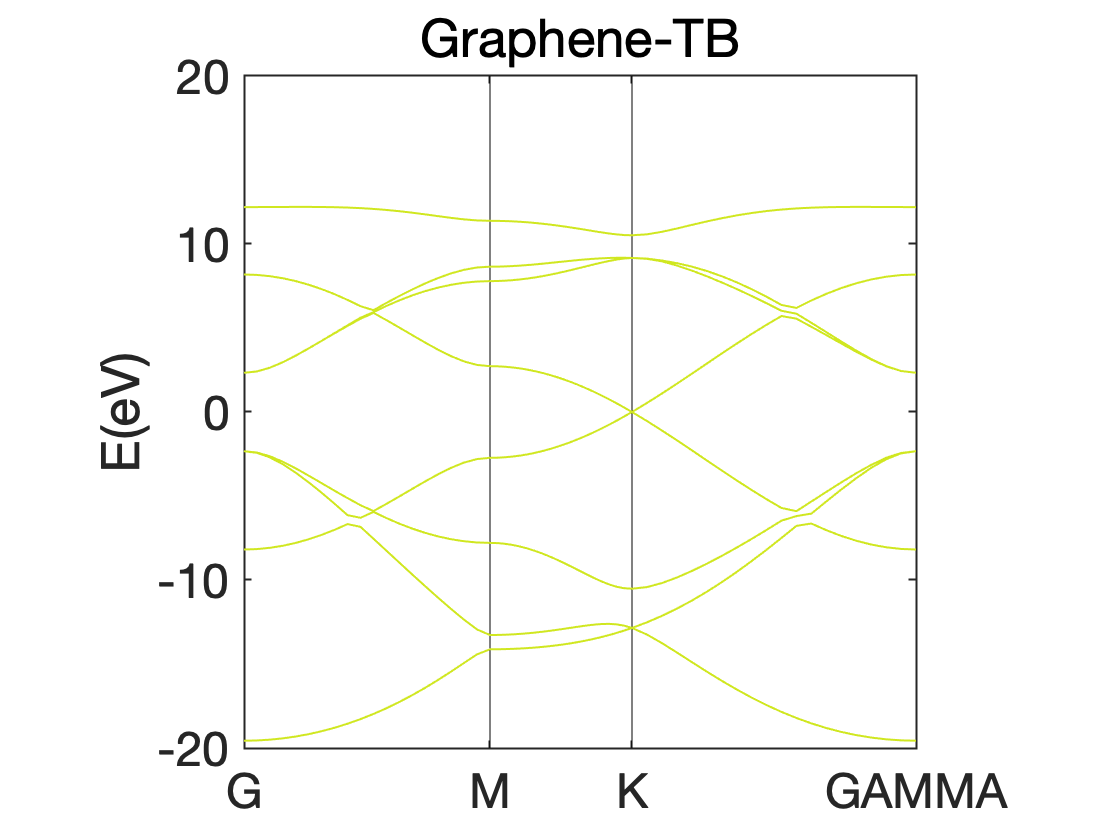

bandplot(EIGENCAR ,[-20,20],"Graphene-TB");

## 定义 BASIS_MAT

- 只取pz

BASIS_MAT = [0 0 0 0 0 0 1 0;0 0 0 0 0 0 0 1];%

- 尝试把 HTB 的8个轨道 投影到2 个轨道的子空间

Graphene_pz = Graphene_n.project(BASIS_MAT);

- 生成能带

EIGENCAR_pz = Graphene_pz.EIGENCAR_gen();

- 画出能带

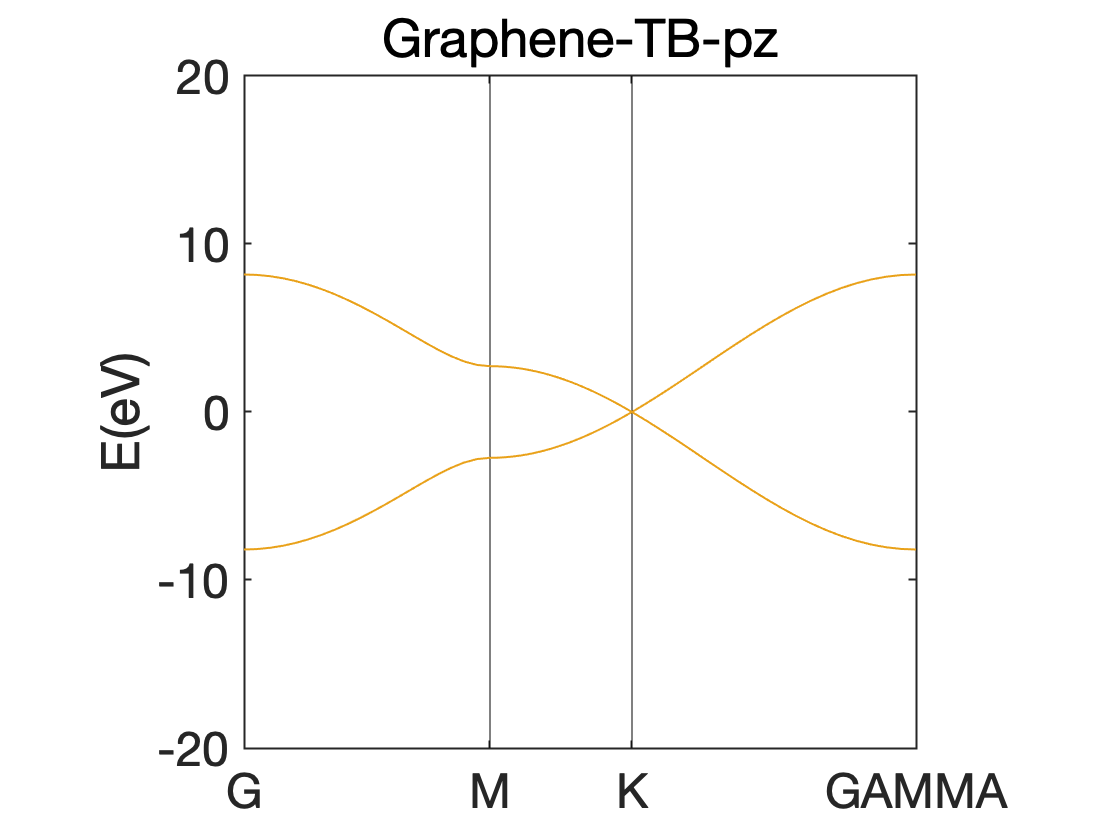

bandplot(EIGENCAR_pz ,[-20,20],"Graphene-TB-pz");